# Chapter 5 Exercise Solutions

#### Exercise 5.1

(a) $p(t) = -\frac{4}{t}$, $q(t) = \frac{2}{t^2}$ and $r(t) = \frac{2\ln(t)}{t^3}$. $p(t)$, $q(t)$ and $r(t)$ are all continuous in the range $[1, 2]$ and $q(t) > 0$ for all $t$ so this BVP has a unique solution.

(b) $p(t) = -(t + 1)$, $q(t) = \cos(t)$ and $r(t) = e^t$. $p(t)$, $r(t)$ and $q(t)$ are all continuous in the range $[0, 2]$ but $q(t) < 0$ in the range $[\frac{\pi}{2}, 2]$ so this BVP does not have a unique solution.

(c) $p(t) = 0$, $q(t) = (t^3 + 5)$ and $r(t) = \sin(t)$. $p(t)$, $r(t)$ and $q(t)$ are all continuous in the range $[0, 1]$ and $q(t) > 0$ in the same range so this BVP has a unique solution.

(d) $p(t) = 0$, $q(t) = 5e^t$ and $r(t) = e^t\sin(3t)$. $p(t)$, $q(t)$ and $r(t)$ are all continuous in the range $[0, 1]$ and $q(t) > 0$ for all $t$ so this BVP has a unique solution.

#### Exercise 5.2

% Define Euler method
function [t, y] = euler(f, tspan, y0, h)

nsteps = floor((tspan(2) - tspan(1)) / h);
m = length(y0);
t = zeros(1, nsteps + 1);
y = zeros(nsteps + 1, m);

t(1) = tspan(1);
y(1,:) = y0;

for n = 1 : length(t) - 1
    y(n+1,:) = y(n,:) + h * f(t(n), y(n,:));
    t(n+1) = t(n) + h;
end

end

% Define ODE function
f = @(t, y) [y(2), -4 * y(1)];

% Define BVP parameters
tspan = [0, 1];     % boundaries of the t domain
bvals = [0, 1];     % boundary values
h = 0.2;            % step length

% Calculate the solution to the IVP using s = 1 and s = 2
[t, y1] = euler(f, tspan, [bvals(1), 1], h);
[t, y2] = euler(f, tspan, [bvals(1), 2], h);

% Print tables of solutions
if true % to keep printed lines togethers
    fprintf("|  t   |     y1     |     y2     |")
    fprintf("----------------------------------")
    for n = 1 : length(t)
        fprintf("|%5.2f | %10.6f | %10.6f |\n", t(n), y1(n,1), y1(n,2))
    end

    fprintf("|  t   |     y1     |     y2     |")
    fprintf("----------------------------------")
    for n = 1 : length(t)
        fprintf("|%5.2f | %10.6f | %10.6f |\n", t(n), y2(n,1), y2(n,2))
    end
end

|  t   |     y1     |     y2     |

----------------------------------

| 0.00 |   0.000000 |   1.000000 |
| 0.20 |   0.200000 |   1.000000 |
| 0.40 |   0.400000 |   0.840000 |
| 0.60 |   0.568000 |   0.520000 |
| 0.80 |   0.672000 |   0.065600 |
| 1.00 |   0.685120 |  -0.472000 |


|  t   |     y1     |     y2     |

----------------------------------

| 0.00 |   0.000000 |   2.000000 |
| 0.20 |   0.400000 |   2.000000 |
| 0.40 |   0.800000 |   1.680000 |
| 0.60 |   1.136000 |   1.040000 |
| 0.80 |   1.344000 |   0.131200 |
| 1.00 |   1.370240 |  -0.944000 |


#### Exercise 5.3

s = 2 - (1 - y2(end,1)) * (2 - 1) / ((1 - y2(end,1)) - (1 - y1(end,1)))

s = 1.4596

% Calculate the solution to the IVP using s = 1.4596
[t, y3] = euler(f, tspan, [bvals(1), s], h);

% Print tables of solutions
if true % to keep printed lines togethers
    fprintf("|  t   |     y1     |     y2     |")
    fprintf("----------------------------------")
    for n = 1 : length(t)
        fprintf("|%5.2f | %10.6f | %10.6f |\n", t(n), y3(n,1), y3(n,2))
    end
end

|  t   |     y1     |     y2     |

----------------------------------

| 0.00 |   0.000000 |   1.459598 |
| 0.20 |   0.291920 |   1.459598 |
| 0.40 |   0.583839 |   1.226063 |
| 0.60 |   0.829052 |   0.758991 |
| 0.80 |   0.980850 |   0.095750 |
| 1.00 |   1.000000 |  -0.688930 |


#### Exercise 5.4


$$y'' + 4y = 0, \qquad y(0) = 0, \qquad y(1) = 1.$$


Using $y'' = \frac{y_{i-1} - 2y_i + y_{i+1}}{h^2}$ then


$$\begin{array}{rl}
\frac{y_{i-1} - 2y_i + y_{i+1}}{h^2} + 4y_i &= 0 \\
    y_{i-1} + (4h^2 - 2)y_i + y_{i+1} &= 0.
\end{array}$$


Since $h = 0.2$, $y_0 = 0$ and $y_5 = 1$ then


$$\begin{array}{rl}
    y_0 &= 0, \\
    y_0 - 1.84 y_1 + y_2 &= 0, \\
    y_1 - 1.84 y_2 + y_3 &= 0, \\
    y_2 - 1.84 y_3 + y_4 &= 0, \\
    y_3 - 1.84 y_4 + y_5 &= 0, \\
    y_5 &= 1,
\end{array}$$


which can be written as the matrix equation


$$ \begin{array}{rl}
    \pmatrix{
        1 & 0 & 0 & 0 & 0 & 0 \cr
        1 & -1.84 & 1 & 0 & 0 & 0 \cr
        0 & 1 & -1.84 & 1 & 0 & 0 \cr
        0 & 0 & 1 & -1.84 & 0 & 0 \cr
        0 & 0 & 0 & 1 & -1.84 & 1 \cr
        0 & 0 & 0 & 0 & 0 & 1
    } 
    \pmatrix{ y_0 \cr y_1 \cr y_2 \cr y_3 \cr y_4 \cr y_5 }
    =
    \pmatrix{ 0 \cr 0 \cr 0 \cr 0 \cr 0 \cr 1 }
\end{array}$$


Solving using MATLAB:

% Define linear system
n = round((tspan(2) - tspan(1)) / h) + 1;
A = eye(n);
b = zeros(n, 1);
b(1) = bvals(1);
b(n) = bvals(2);

for i = 2 : n - 1
    A(i,i-1) = 1;
    A(i,i) = 4 * h^2 - 2;
    A(i,i+1) = 1;
end

% Solve linear system
y = A \ b;
t = tspan(1) : h : tspan(2);

% Print table of solutions
if true % to keep printed lines togethers
    fprintf("|  t   |     y1     |")
    fprintf("---------------------")
    for n = 1 : length(t)
        fprintf("|%5.2f | %10.6f |\n", t(n), y(n))
    end
end

|  t   |     y1     |

---------------------

| 0.00 |   0.000000 |
| 0.20 |   0.433748 |
| 0.40 |   0.798096 |
| 0.60 |   1.034749 |
| 0.80 |   1.105842 |
| 1.00 |   1.000000 |


#### Exercise 5.5

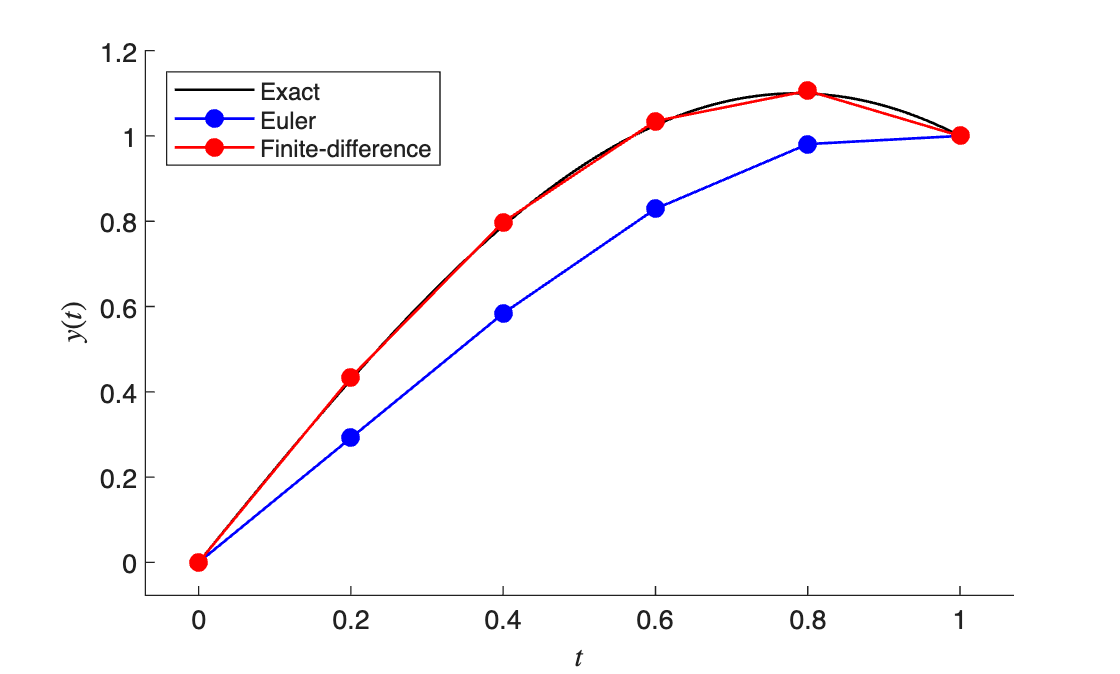

% Define exact solution
exact = @(t) sin(2 * t) / sin(2);

% Calculate exact solution 
texact = linspace(tspan(1), tspan(2), 100);
yexact = exact(texact);

% Plot solutions
hold on
h(1) = plot(texact, yexact, 'k', LineWidth=1);
h(2) = plot(t, y3(:,1), 'b-o', MarkerFaceColor='b', LineWidth=1);
h(3) = plot(t, y, 'r-o', MarkerFaceColor='r', LineWidth=1);
hold off
xlabel('$t$', Interpreter='latex')
ylabel('$y(t)$', Interpreter='latex')
legend(h, {'Exact', 'Euler', 'Finite-difference'}, Location='northwest')
axis padded